# Deflection Analysis of Bracket for Multiple Materials

This example shows how to perform a parameter sweep of material properties to determine the material with minimum deflection caused by a given load. Lastly, for such material we compute a load deflection curve. This analysis leverages parallel computing to speed up the results of the simulation. Please refer to [Deflection Analysis of Bracket](https://www.mathworks.com/help/pde/examples/deflection-analysis-of-a-bracket.html) for a more detail walkthrough of the solution methodology. 

## Import Material Properties and Define Problem

We import the parameters from a text file of materials to be analyzed. Also, we start a [parallel pool](https://www.mathworks.com/help/distcomp/run-code-on-parallel-pools.html) since we will leverage parallelization for our computations.

clear
gcp;
material_parameters = readtable('Materials_ParametersList.txt','ReadVariableNames',false,'HeaderLines',1);
material_parameters.Properties.VariableNames = {'Material','YoungsModulus','PoissonsRatio'};
material_parameters.Properties.VariableUnits = {'','GPa',''} % Keep track of units on our table

material_parameters = 6×3 table
     Material      YoungsModulus    PoissonsRatio
    ___________    _____________    _____________
    'Steel'              200             0.3     
    'Aluminium'           69            0.32     
    'Titanium'         110.3            0.27     
    'Copper'             117            0.33     
    'Bronze'             120            0.34     
    'Brass'              125            0.34     


idx_max = size(material_parameters,1); % Number of materials to consider
distributedLoad = 1e4; % Applied load in Pascals
bracketThickness = 1e-2; % Thickness of horizontal plate with hole, meters

Model = cellfun(@(~) createpde('structural','static-solid'),material_parameters.Material,'UniformOutput',false);
YoungMV = material_parameters.YoungsModulus*1e9; % GPa 
PoissR = material_parameters.PoissonsRatio;

## Create Structural Analysis Models and Find Solutions

The first step in solving a linear elasticity problem is to create a structural analysis model. This is a container that holds the geometry, structural material properties, body and boundary loads, boundary constraints, and mesh. We perform this step for all materials using [parfor](https://www.mathworks.com/help/distcomp/parallel-for-loops-parfor.html) and compute the solution of all materials in parallel. Compare solution time of for vs parfor using tic/toc.

pb = cell(1,idx_max);
results = cell(1,idx_max);

parfor ii = 1:idx_max
    pb{ii} = setupFEA(Model{ii},YoungMV(ii),PoissR(ii),distributedLoad);
    results{ii} = solve(pb{ii});    
end

## Examine the Solutions

Find the minimum deflection of the bracket in the $z$ direction.

minUz = cellfun(@(x) min(x.Displacement.uz),results);
[mUz,Imin] = max(minUz);
fprintf(['The material with the minimum deflection in the z-direction is '...
    material_parameters.Material{Imin} ' with ' num2str(mUz) ' m']);

The material with the minimum deflection in the z-direction is Steel with -4.4895e-05 m

material_parameters.Max_Deflection = abs(minUz)' % Append deflection values to our table

material_parameters = 6×4 table
     Material      YoungsModulus    PoissonsRatio    Max_Deflection
    ___________    _____________    _____________    ______________
    'Steel'              200             0.3           4.4895e-05  
    'Aluminium'           69            0.32            0.0001301  
    'Titanium'         110.3            0.27           8.1412e-05  
    'Copper'             117            0.33           7.6708e-05  
    'Bronze'             120            0.34           7.4772e-05  
    'Brass'              125            0.34           7.1781e-05  

## Plot Z-Displacement for All Materials

To visualize the solutions, plot the components of the solution vector. The maximal deflections are in the $z$-direction. We compare all solutions using the same colorbar range. Notice the color difference for the material with least vs. largest deflection.

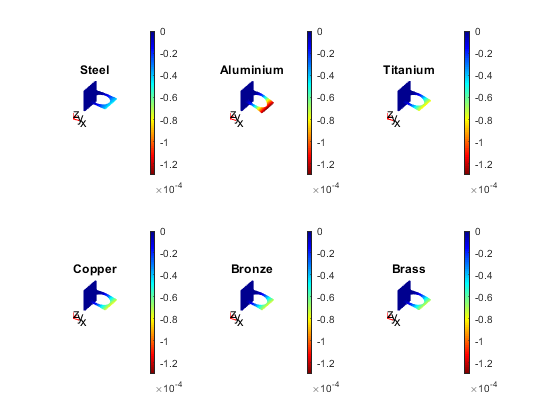

for jj = 1:idx_max
    subplot(2,3,jj)
    h = pdeplot3D(pb{jj},'ColorMapData',results{jj}.Displacement.uz,...
        'Deformation',results{jj}.Displacement,'DeformationScaleFactor',5e2);
    cm = colormap(gca,jet);
    colormap(gcf,flip(cm));
    caxis(gca,[min(minUz) 0])
    title(material_parameters.Material(jj))
end

## Compute Load/Deflection Curve

We compute load deflection curves for each material. We loop over all materials for 10 different loads in the range [100,100e6] Pa. That is, 60 different models total. Use meshgrid to iterate on a single loop of all material parameter and load combinations.

F_Load = linspace(1e2,1e8,10);
F_Load_size = size(F_Load,2);
[X,Y] = meshgrid(1:idx_max,F_Load); 
lD_result = nan(F_Load_size,idx_max);

parfor ii = 1:numel(X)
   mdl = pb{X(ii)};
   lD_result(ii) = solveLD(mdl,Y(ii)); 
end

## Visualize Curves for all Materials

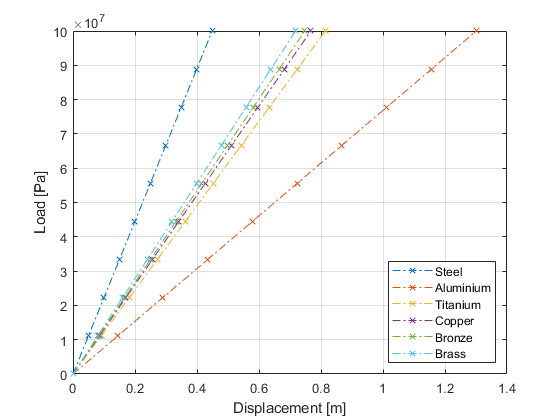

figure
plot(lD_result,F_Load,'-.x')
xlabel('Displacement [m]')
ylabel('Load [Pa]')
legend(material_parameters.Material,'Location','southeast')
grid on;

## Helper Functions

Helper functions to assemble problem and solve load deflection models.

function modelN = setupFEA(modelN,YoungM,PoissonR,distrL)
    modelN.Geometry = importGeometry(modelN,'BracketWithHole.stl');
    structuralProperties(modelN,'Cell',1,'YoungsModulus',YoungM,'PoissonsRatio',PoissonR);
    structuralBC(modelN,'Face',4,'Constraint','fixed');
    structuralBoundaryLoad (modelN,'Face',8,'SurfaceTraction',[0;0;-distrL]);
    bracketThickness = 1e-2; % Thickness of horizontal plate with hole, meters
    generateMesh(modelN,'Hmax',bracketThickness);
end

function ld_mat = solveLD(modelM,ldm)
structuralBoundaryLoad (modelM,'Face',8,'SurfaceTraction',[0;0;-ldm]);
ld_result = solve(modelM);
ld_mat = abs(min(ld_result.Displacement.uz));
end

*Copyright 2014-2018 The MathWorks, Inc.*